### **Digital Signal Processing / AVE **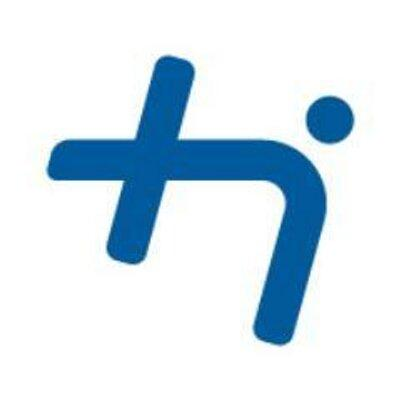

#### **Prof. Dr. Michael Mecking**

# **Filter Design for Interference Elimination**

### Problem 1

Load the file *bowie_interference.mat* provided in Moodle. You’ll find a discrete-time audio signal $x[n]$ as well as the sampling frequency $f_S$.  

Listen to the sound file using MATLAB’s *sound* command (check the documentation first). 

What do you notice? Yes, there’s an interfering signal that shouldn’t be there…

% your code...
sound(x, fs);

### Problem 2

Apply what you’ve learned so far in the module on Digital Signal Processing to design an LTI system that eliminates the interfering signal without significantly altering (in this case ch-ch-changing) Bowie:

- Analyse the discrete-time signal $x[n]$. 

- Design a digital filter that eliminates the interference without significantly reducing the useful signal. (PS: Bowie is extremely useful!) 

You may use any code applied in the lab exercises so far - feel free to copy and paste. In your own interest, do not use ChatGPT!

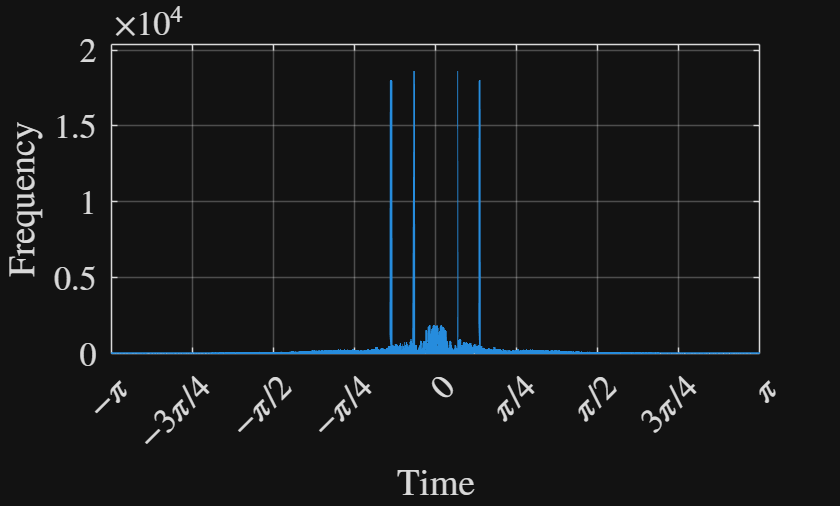

% ch-ch-change the signal x, i.e., eliminate the interferer

% your analysis and design...

N = length(x);
X = fft(x);
X = circshift(X, length(X) / 2);
Omega = linspace(-pi*(1-1/length(X)), pi, length(X));
% T = N / fs;
% f = (0:N-1) / T;

% range = 1:(N)/2;

figure
plot(Omega, abs(X), 'LineWidth',1.5)
axis([-pi pi 0 1.1*max(abs(X))])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("Time", Interpreter="latex")
ylabel("Frequency", Interpreter="latex")